# Asesoria

### Metodos Numericos

#### 2022-2S : 12/09/2022

clear
syms f(x)
syms alpha A real

A = (sym(pi) / (2 * alpha^2))^(-1/4);
f(x) = A * exp(-alpha^2 * x^2);
xbar = int(x * f(x)^2, -inf, inf)

$$xbar = 0$$

x2bar = simplify(int(x^2 * f(x)^2, -inf, inf))

$$x2bar = \frac{\left|\alpha \right|}{4\,{\left(\alpha^{2}\right)}^{3/2}}$$

I = int(exp(-2 * alpha^2 * x^2), -inf, inf)

$$I = \frac{\sqrt{2}\,\sqrt{\pi }}{2\,\sqrt{\alpha^{2}}}$$

clear
syms psi(x)
syms alpha h m

psi(x) = exp(-(m * alpha^2 * x^2 / (2 * h^2) ) ^(1/2));
dpsi(x) = diff(psi, x)

$$dpsi(x) = -\frac{\alpha^{2}\,m\,x\,{\mathrm{e}}^{-\sqrt{\frac{\alpha^{2}\,m\,x^{2}}{2\,h^{2}}}}}{2\,h^{2}\,\sqrt{\frac{\alpha^{2}\,m\,x^{2}}{2\,h^{2}}}}$$

d2psi(x) = diff(dpsi, x)

$$d2psi(x) = \begin{array}{l} \frac{\sigma_{1}}{2\,h^{2}}-\frac{\sigma_{1}}{2\,h^{2}\,\sigma_{2}}+\frac{\alpha^{4}\,m^{2}\,x^{2}\,{\mathrm{e}}^{-\sigma_{2}}}{4\,h^{4}\,{\left(\frac{\alpha^{2}\,m\,x^{2}}{2\,h^{2}}\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=\alpha^{2}\,m\,{\mathrm{e}}^{-\sigma_{2}}\\ \sigma_{2}=\sqrt{\frac{\alpha^{2}\,m\,x^{2}}{2\,h^{2}}} \end{array}$$

expand(d2psi)

$$ans(x) = \begin{array}{l} \frac{\alpha^{2}\,m\,\sigma_{1}}{2\,h^{2}}-\frac{\sqrt{2}\,\alpha^{2}\,m\,\sigma_{1}}{2\,h^{2}\,\sqrt{\sigma_{2}}}+\frac{\sqrt{2}\,\alpha^{4}\,m^{2}\,x^{2}\,\sigma_{1}}{2\,h^{4}\,{\sigma_{2}}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\sigma_{2}}}{2}}\\ \sigma_{2}=\frac{\alpha^{2}\,m\,x^{2}}{h^{2}} \end{array}$$

Pasarles tabla de cambios de variable

clear
syms x

help lsline

  Entrada  - X es el vector de abscisas   1 x n
           - Y es el vector de ordenadas  1 x n
  Salida   - A es el coeficiente de  x  en  Ax + B
           - B es el coeficiente constante en  Ax + B



help lspoly

  Entrada   - X es el vector de abscisas   1 x n
            - Y es el vector de ordenadas  1 x n
            - M es el grado del polinomio por minimos cuadrados
  Salida    - C es la lista de coeficientes para el polinomio



help cheby

  Entrada   - fun es la funcion introducida con @
            - N es el grado del polinomial interpolante de Chebyshev
            - a es el extremo izquierdo
            - b es el extremo derecho
  Salida    - C es la lista de coeficientes para el polinomio
            - X contiene las abscisas
            - Y contiene las ordenadas



f = @(x) sin(x);

[C, X, Y] = cheby( f, 6, -6, 6)

C =    -0.0000   -0.5536   -0.0000   -0.2254   -0.0000    0.6818   -0.0000


X =     5.8496    4.6910    2.6033    0.0000   -2.6033   -4.6910   -5.8496


Y =    -0.4202   -0.9998    0.5127    0.0000   -0.5127    0.9998    0.4202


[C, L] = lagran(X, Y)

C =    -0.0000    0.0014    0.0000   -0.0673   -0.0000    0.5887    0.0000


L =     0.0000    0.0003   -0.0013   -0.0073    0.0065    0.0380   -0.0000
   -0.0001   -0.0006    0.0050    0.0235   -0.0283   -0.1329    0.0000
    0.0002    0.0005   -0.0099   -0.0258    0.1329    0.3461   -0.0000
   -0.0002    0.0000    0.0123    0.0000   -0.2222    0.0000    1.0000
    0.0002   -0.0005   -0.0099    0.0258    0.1329   -0.3461    0.0000
   -0.0001    0.0006    0.0050   -0.0235   -0.0283    0.1329   -0.0000
    0.0000   -0.0003   -0.0013    0.0073    0.0065   -0.0380    0.0000


P = @(x) polyval(C, x);

digits(4)

vpa(poly2sym(C, x))

$$ans = -1.22e-19\,x^{6}+0.001403\,x^{5}+8.674e-19\,x^{4}-0.06731\,x^{3}-1.11e-16\,x^{2}+0.5887\,x+1.511e-16$$

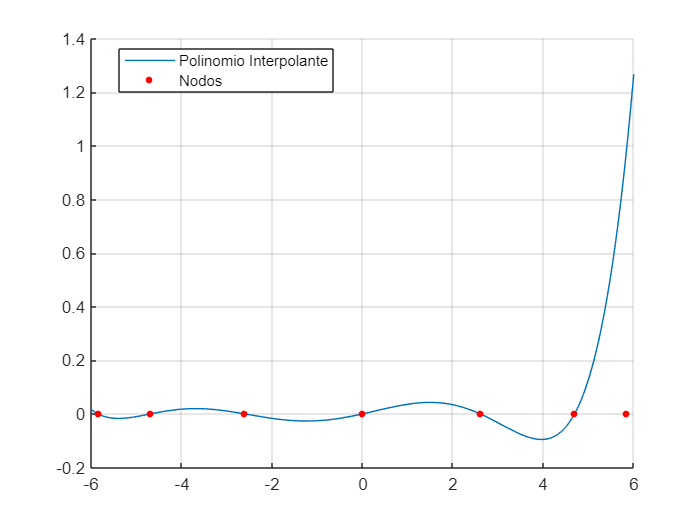

L1 = @(x) polyval(L(1, :), x);

clf('reset')
hold on
fplot(L1, [-6, 6], 'DisplayName', 'Polinomio Interpolante')
plot(X, zeros(size(X)), '.r', 'MarkerSize', 12, 'DisplayName', 'Nodos')
legend('Location','best')
grid on
hold off

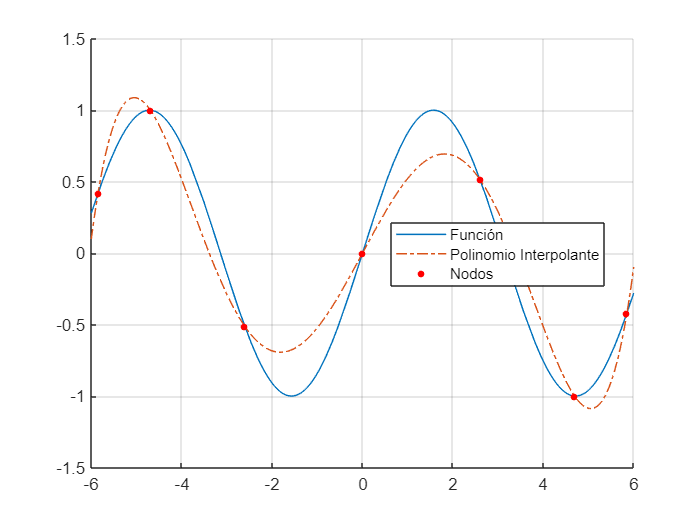

clf('reset')
hold on
fplot(f, [-6, 6], 'DisplayName', 'Función')
fplot(P, [-6, 6], '-.', 'DisplayName', 'Polinomio Interpolante')
plot(X, Y, '.r', 'MarkerSize', 12, 'DisplayName', 'Nodos')
legend('Location','best')
grid on
hold off

syms f(x)

f(x) = sin(x);
d7f(x) = diff(f, x, 7);

Error = @(x) abs(d7f(0) / factorial(7) * prod(X - x));
cota = eval(abs(d7f(0) / factorial(7) * 1 / 2^6))

cota = 3.1002e-06


clf('reset')
hold on
fplot(Error, [-6, 6], 'DisplayName', 'Error')

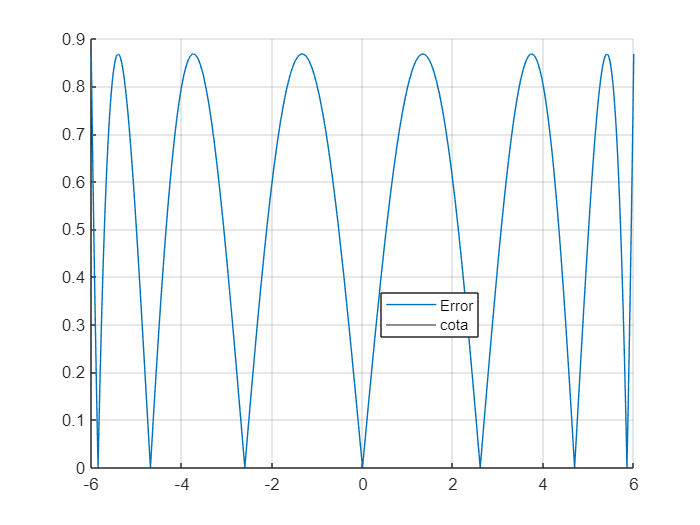

yline(cota, 'DisplayName', 'cota')
legend('Location','best')
grid on
hold off

X = linspace(-6, 6, 1e3);

E = P(X) - f(X);
eval(norm(E, 'inf'))

ans = 0.3410